clear;clc;close all;
pointnum1 = 0;
pointnum2 = 0;
w0 = 8;
start = 5;
endo  = 6;
nbo = endo-start+1;
nb = 100;
number = nbo*nb;
mypoint = zeros(number+1,3);
for n = 1:nbo    
    %scale((n-1)*nb+1:n*nb) = (2^(n-1):(2^n-2^(n-1))/nb:2^n-(2^n-2^(n-1))/nb);
    scale((n-1)*nb+1:n*nb) = (2^(start+n-2):(2^(start+n-1)-2^(start+n-2))/nb:2^(start+n-1)-(2^(start+n-1)-2^(start+n-2))/nb);
end

fs = 100;
N = 300;
T = N/fs;
dt = 1/fs; % 采样间隔
t = 0:dt:T-dt; % 时间刻度向量
f1 = 10; % 频率分量1
f2 = 30; % 频率分量2
x = cos(2*pi*f1*t)+cos(2*pi*f2*t); % 基带信号
sig = load("203.txt");
sig = sig(:,2);
%plot(sig)
S1 = 1024;
fc = w0/2/pi;
get_Morther = @(w) sqrt(2*pi)*exp(-(((w-w0).^2)/2));
get_Morlet_ft = @(a,w) sqrt(2*pi)*exp(-(((a*w-w0).^2)/2));
%tranditional

y1 = sig(1:N);
y1_ft = fft(y1);
y_fft = zeros(N,1);
y_fft(1:N/2)=y1_ft(1:N/2);

% w1 = (0:2*w0/fs:2*w0-2*w0/fs);
% f_ft = w1/(2*pi);
% matx1 = zeros(1024,number);
% mat1_ft = zeros(1024,number);
% tic;
% for n = 1:number
%     M1 = get_Morlet_ft(scale(n),w1);
%     %plot(M1)
%     M1 = M1';
%     matx1(:,n) = y_fft.*M1;
%     mat1_ft(:,n) = ifft(matx1(:,n));
% end 
% time1 = toc
% cwt_sig1 = abs(mat1_ft.');
% image(cwt_sig1,"CDataMapping","scaled");
% ysca = scale;
% set(gca,'yticklabels',ysca)

%
w2 = (0:2*w0/N:2*w0-2*w0/N);
morther_wave = get_Morlet_ft(1,w2);
%plot(morther_wave)
morther_wave = morther_wave';


matx2 = zeros(N,number);
matrix_ft= zeros(N,number);

matx3 = zeros(N,number);
matrix_ft3 = zeros(N,number);
a = 2

a = 2

Nc = (N/(2*fc))*fc;
deltaN = round((N/(2*fc))*(sqrt(a)/2));
N1=round((N/(2*fc))*(fc-sqrt(a)/2));
N2=round((N/(2*fc))*(fc+sqrt(a)/2));
Nlength = N2-N1+1;
%plot(morther_wave(N1:N2));
tic;
for k = 1:number
    %point = round((2*deltaN)/scale(k));
    step = scale(k);
    point1 = round(N/scale(k));
    wave_ft1 = zeros(point1,1);
    pointnum1 = pointnum1+point1;
    for n = 1:point1   
        wave_ft1(n) = morther_wave(round((n-1)*step+1));
        wave_all1(n,k) = wave_ft1(n);
    end
    %plot(wave_ft1)
    sig2 = y_fft(1:point1);
    matx2(1:point1,k) = sig2.*wave_ft1;
    matrix_ft(:,k) = ifft(matx2(:,k));
    mypoint(k,1) = point1;
    %mypoint(k,3) = length(sig2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %point = round((2*deltaN)/scale(k));
    N_star = ceil(N1/scale(k));
    %Nc_sig = round(fs/2/scale(k));
    deltaN_sig = round((N/(2*fc))*(sqrt(a)/2)/scale(k));
    %N_st = Nc_sig - deltaN_sig;
    %N_end = Nc_sig + deltaN_sig;
    %point = N_end - N_st+1;
    point = 2*deltaN_sig+1;
    pointnum2 = pointnum2+point;
    wave_ft = zeros(point,1);
    for n = 1:point 
        wave_ft(n) = morther_wave(round(N1+(n-1)*step)); 
        wave_all2(n,k) = wave_ft(n);
    end
    
    %plot(wave_ft)
    sig2 = y_fft(N_star:N_star+point-1);
    matx3(N_star:N_star+point-1,k) = sig2.*wave_ft;
    matrix_ft3(:,k) = ifft(matx3(:,k));
    mypoint(k,2) = point;
    %mypoint(k,3) = length(sig2);

end
mypoint(number+1,1) = pointnum1;
time2 = toc

time2 = 0.0187

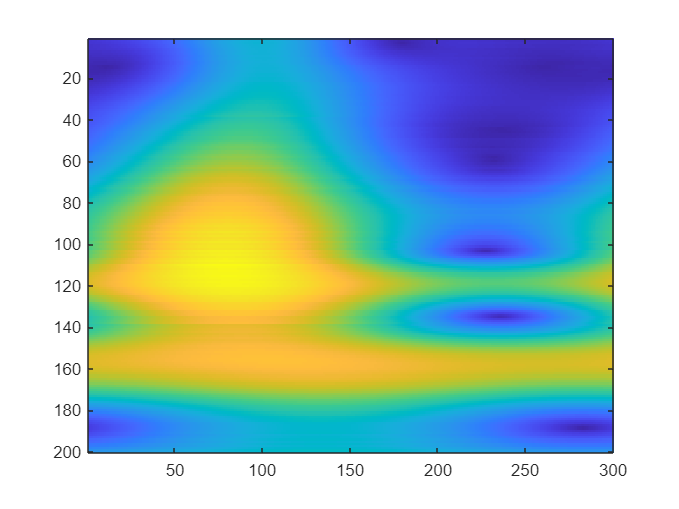

cwt_sig2 = abs(matrix_ft.');
image(cwt_sig2,"CDataMapping","scaled");

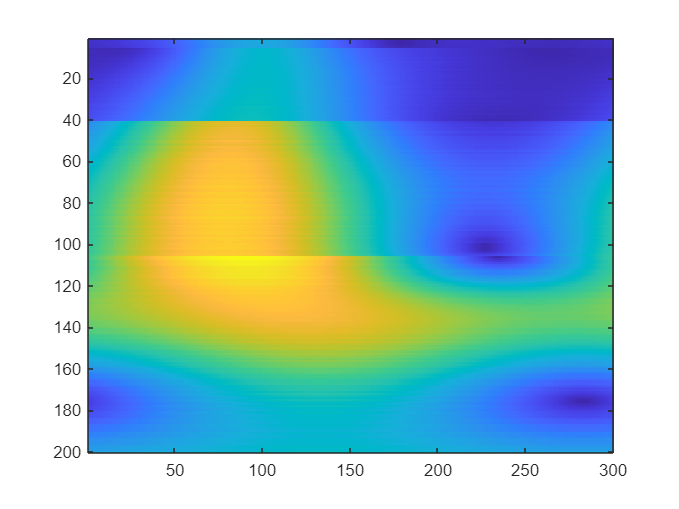

mypoint(number+1,2) = pointnum2;
cwt_sig3 = abs(matrix_ft3.');
image(cwt_sig3,"CDataMapping","scaled");